% Get numeric columns
ld = loaddata{:,1};
pv = pvdata{:,1};

% Average every 30 rows → 48×1
blk = 30;                                   % half-hour block
m   = floor(numel(ld)/blk)*blk;
Load48 = mean(reshape(ld(1:m),blk,[]),1).'; % use 'omitnan' if needed
PV48   = mean(reshape(pv(1:m),blk,[]),1).';

% Half-hour index in hours (0, 0.5, …, 23.5)
HalfHour = (0:numel(Load48)-1).' / 2;
HalfHourly = table(HalfHour, Load48, PV48);

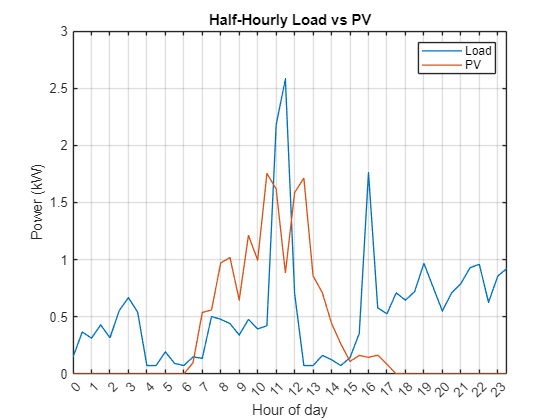

% Plot (kW vs hour)
figure;
plot(HalfHourly.HalfHour, [HalfHourly.Load48 HalfHourly.PV48], 'LineWidth',1);
grid on; xlim([0 23.5]); xticks(0:23);
xlabel('Hour of day'); ylabel('Power (kW)');
title('Half-Hourly Load vs PV');
legend({'Load','PV'}, 'Location','northeast');